# Inner Controller Identification

## Setup

load 'quad_copter_models.mat';
USE_REAL_DATA = false;

For the VRFT process we consider the `PitchRateModel` and the `Mixer` as a single block. This way the parameters of the PID are unaffected by the Mixer gain and can be directly compared to the controller obtained with $H_\infty$ synthesis.

PlantModel    = PitchRateModel * Mixer;
PlantModel_dt = c2d(tf(PlantModel), Ts);

## Reference Model. 

REWRITE ME !!

Since we want to compare the controller obtained with $H_\infty$ synthesis and the one obtained with the VRFT we cannot use any reference model. In the end the two closed loop models should be similar. This means that the reference model used for VRFT should be the complementary sensitivity of the closed loop system with $H_\infty$ synthesis.

% ReferenceModel = InnerLoop_Hinf;
% ReferenceModel_dt = c2d(tf(ReferenceModel), Ts);

InnerReferenceModel = mk_2nd_order(60, .7);
InnerReferenceModel_dt = c2d(InnerReferenceModel, Ts);

## Making some I/O Data

To run the VRFT we need a set of I/O data. The real data that we have inputs $\delta M$ into the quad-copter and outputs $\dot{q}$. To mimic this we pass in a PRBS input into the `PitchRateModel` block.

**Note**: we only assume that the input provided is $\delta M$since we cannot replicate the results experimentally. I believe that the data is actually a percentage of some reference toque value.

If `USE_REAL_DATA` is set to true then we will load the experimental data. Otherwise we will generate a similar PRBS sequence and use that instead.

vrft_data = struct();

if USE_REAL_DATA
    ol_data = load('dati_id_ol.mat');
    
    vrft_data.time  = ol_data.t;
    vrft_data.dM    = ol_data.u;
    vrft_data.q_dot = deg2rad(ol_data.y);
    vrft_data.type = 'Experimental';
else
    % I/O Signals
    N = 16 / Ts; % Sample size. We divide it by Ts to ensure that we have 16s of samples.
    vrft_data.time = [0:(N-1)] * Ts;
    
    % PRBS sequence with parameters chosen to match the experimental data
    vrft_data.dM    = idinput(N, 'prbs', [0, .045], [-1, 1]);
    vrft_data.q_dot = lsim(PitchRateModel * Mixer, vrft_data.dM, vrft_data.time);
    vrft_data.type  = 'Simulated';
end

The data we have goes from $\delta \Omega$ to $\dot{q}$. However, for the VRFT, we want the data from $\delta M$to $\dot{q}$. This means that we need to include the effect of the `Mixer` in the data. Theoretically the mixer introduces a $10ms$ delay into the signal. At the moment we are chosing to ignore it. 

vrft_data.dOmega = lsim(Mixer, vrft_data.dM, vrft_data.time);

Let's take a look at what we have.

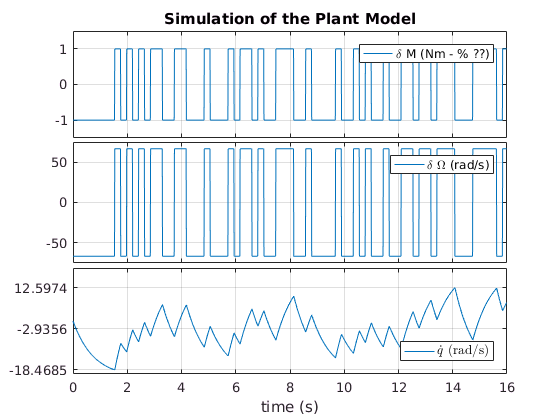

figure()
    subplot 311
        plot(vrft_data.time, vrft_data.dM); 
        legend('\delta M (Nm - % ??)'); ylim([-1.5, 1.5]);
        
        if USE_REAL_DATA
            title('Experimental I/O Data');
        else
            title('Simulation of the Plant Model');
        end
    subplot 312 
        plot(vrft_data.time, vrft_data.dOmega); 
        legend('\delta \Omega (rad/s)');ylim([-75, 75]);
    subplot 313
        plot(vrft_data.time, vrft_data.q_dot); 
        legend({'$$\dot{q}$$ (rad/s)'}, ...
            'Location', 'southEast', 'Interpreter', 'latex', 'FontSize', 10); 
        xlabel('time (s)'); 
condense_subplots('tight', true)        

## VRFT Time !

Note: `VRFT1_ry_theta` is an extension of the `VRFT1_ry` method that also exposes the value of the parameter vector. The only changes from the original file are related to this. 

[OptimalInnerController, Theta] = ...
    VRFT1_ry_theta(vrft_data.dM, vrft_data.q_dot, InnerReferenceModel_dt, PIDControllerClass_dt, [], [], []);

fprintf('The optimal PID parametters for the inner controller are: \n');

The optimal PID parametters for the inner controller are: 


fprintf('Kp = %+7g, Original: %-7g\n', Theta(1), Ri.Kp);

Kp = +1.2731, Original: 0.3    


fprintf('Ki = %+7g, Original: %-7g\n', Theta(2), Ri.Ki);

Ki = +1.23153, Original: 0.3    


fprintf('Kd = %+7g, Original: %-7g\n', Theta(3), Ri.Kd);    

Kd = -0.00779524, Original: 0.05   



cloop = loopsens(PlantModel_dt, OptimalInnerController); 
InnerLoop_VRFT = cloop.Ti;

disp('#==============')

#==============


disp('Compl. Sensitivity with |OptimalController|:')

Compl. Sensitivity with |OptimalController|:


zpk(InnerLoop_VRFT)


ans =
 
  From input "du" to output "uC":
    0.13827 (z-0.9904) (z+0.6458)
  ----------------------------------
  (z-0.9905) (z^2 - 1.226z + 0.4558)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



disp(' ')

disp('Reference Model:')

Reference Model:


zpk(InnerReferenceModel_dt)


ans =
 
    0.13476 (z+0.7543)
  -----------------------
  (z^2 - 1.195z + 0.4317)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



disp('#==============')

#==============


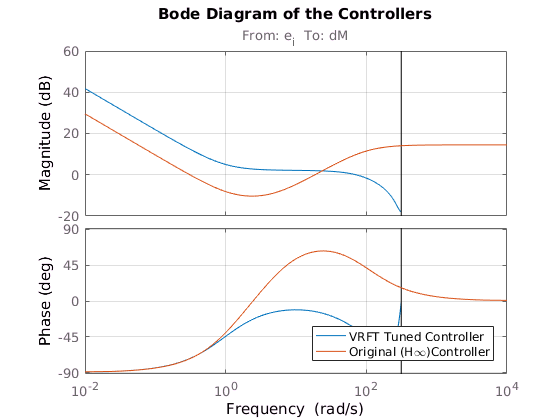


figure()
    bode(OptimalInnerController, Ri);
    title('Bode Diagram of the Controllers'); 
    legend('VRFT Tuned Controller', 'Original (H\infty)Controller', 'location', 'SouthEast');
    grid on;

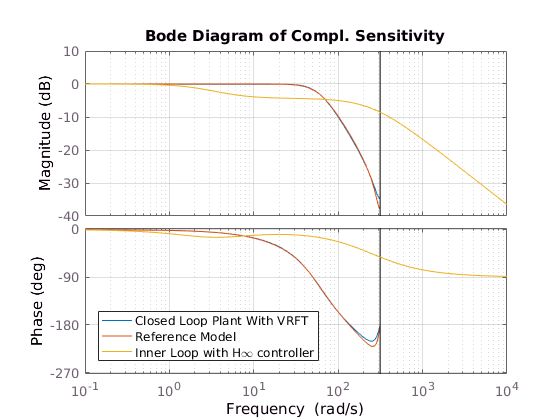


figure()
    bode(InnerLoop_VRFT, InnerReferenceModel_dt, InnerLoop_Hinf);
    title('Bode Diagram of Compl. Sensitivity');
    legend('Closed Loop Plant With VRFT', 'Reference Model', ...
        'Inner Loop with H\infty controller', 'location', 'SouthWest');
    grid on;

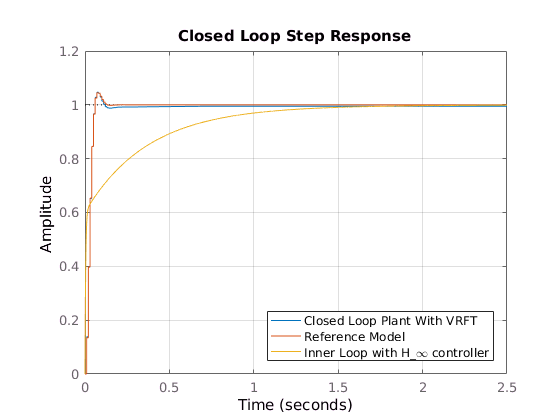

    
figure()
    step(InnerLoop_VRFT, InnerReferenceModel_dt, InnerLoop_Hinf);
    title('Closed Loop Step Response');
    legend('Closed Loop Plant With VRFT', 'Reference Model', ...
        'Inner Loop with H_\infty controller', 'location', 'SouthEast');
    grid on;    

For convenience we will save some of the data we used here. In the outer VRFT we will need access to the input and output signals we used to generate the inner controller. We will also keep a copy of the generated controller for obvious reasons.

save('quad_copter_models.mat', ...
    'OptimalInnerController', 'vrft_data', 'InnerLoop_VRFT', ...
    'OuterReferenceModel_dt', '-append');